---------------------------------------


---------------------------------------


---------------------------------------


f(t,y) = 3y, 0<t<10


-------Using ode45 solver


totaltime = 0.0392

Total function evaluations = 373


Time per function evaluation = 0.00010517


ans = struct with fields:
     nsteps: 60
    nfailed: 2
    nfevals: 373


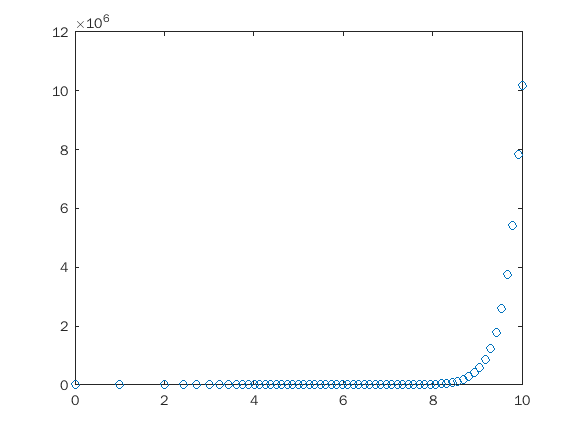

-------Using ode113 solver


totaltime = 0.0428

Total function evaluations = 122


Time per function evaluation = 0.00035052


ans = struct with fields:
     nsteps: 59
    nfailed: 3
    nfevals: 122


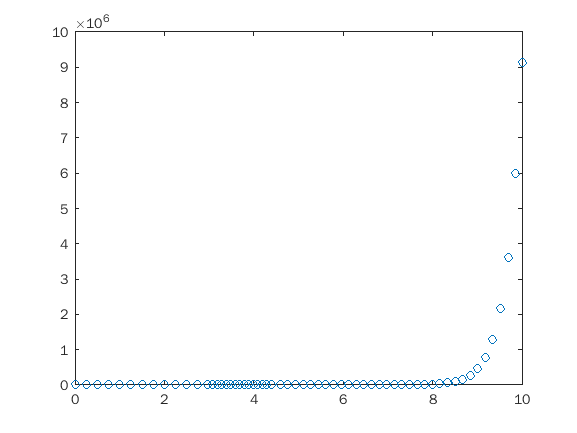

-------Using ode23s solver


totaltime = 0.0546

Total function evaluations = 1728


Time per function evaluation = 3.1579e-05


ans = struct with fields:
      nsteps: 430
     nfailed: 3
     nfevals: 1728
        npds: 430
    ndecomps: 433
     nsolves: 1299


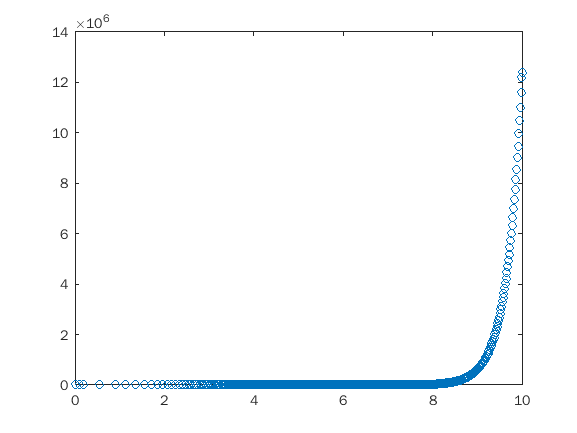

---------------------------------------


---------------------------------------


---------------------------------------


f(t,y) = 3y, 0<t<10  with pause in function evaluation


-------Using ode45 solver


totaltime = 0.4826

Total function evaluations = 373


Time per function evaluation = 0.0012939


ans = struct with fields:
     nsteps: 60
    nfailed: 2
    nfevals: 373


-------Using ode113 solver


totaltime = 0.1271

Total function evaluations = 122


Time per function evaluation = 0.0010417


ans = struct with fields:
     nsteps: 59
    nfailed: 3
    nfevals: 122


-------Using ode23s solver


totaltime = 0.3054

Total function evaluations = 1728


Time per function evaluation = 0.00017673


ans = struct with fields:
      nsteps: 430
     nfailed: 3
     nfevals: 1728
        npds: 430
    ndecomps: 433
     nsolves: 1299


---------------------------------------


---------------------------------------


---------------------------------------


f(t,y) = y^2-y^3, 0<t<2.e6


-------Using ode45 solver


totaltime = 1.0863

Total function evaluations = 1928875


Time per function evaluation = 5.6316e-07


ans = struct with fields:
     nsteps: 301367
    nfailed: 20112
    nfevals: 1928875


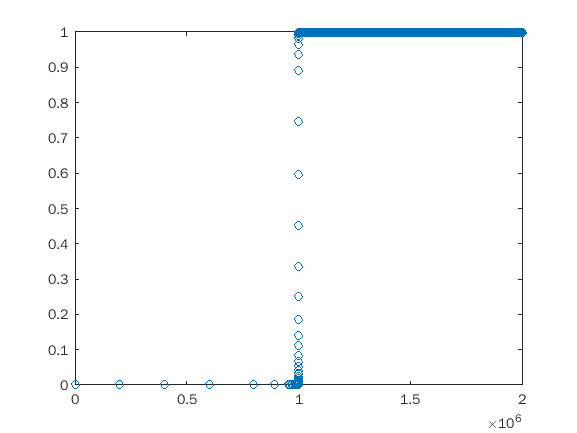

-------Using ode113 solver


totaltime = 6.4744

Total function evaluations = 1242358


Time per function evaluation = 5.2114e-06


ans = struct with fields:
     nsteps: 581655
    nfailed: 79047
    nfevals: 1242358


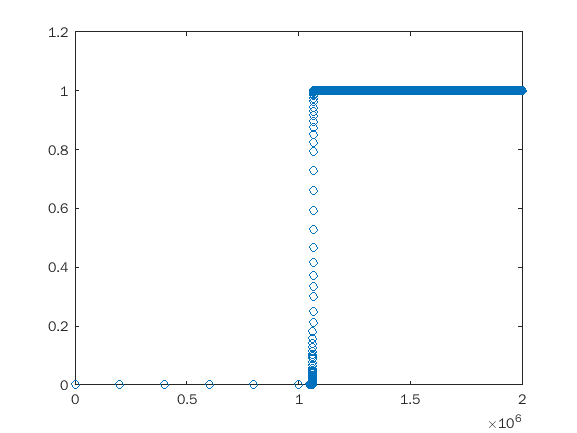

-------Using ode23s solver


totaltime = 0.0139

Total function evaluations = 760


Time per function evaluation = 1.8243e-05


ans = struct with fields:
      nsteps: 182
     nfailed: 15
     nfevals: 760
        npds: 182
    ndecomps: 197
     nsolves: 591


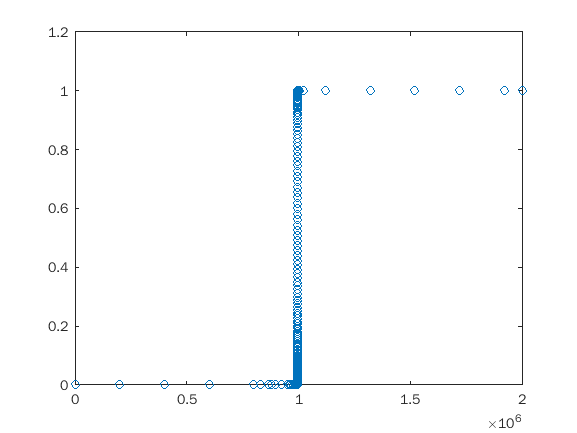

clear all 
close all
opts = odeset('reltol',1.e-5,'stats','off');

for i = 1:3
    

    if i == 1
        disp('---------------------------------------')
        disp('---------------------------------------')
        disp('---------------------------------------')
        disp('f(t,y) = 3y, 0<t<10')
        y0 = 1.e-6;
        tfinal = 10;
    elseif i == 2
        disp('---------------------------------------')
        disp('---------------------------------------')
        disp('---------------------------------------')
        disp('f(t,y) = 3y, 0<t<10  with pause in function evaluation')
        y0 = 1.e-6;
        tfinal = 10;
    elseif i == 3
        disp('---------------------------------------')
        disp('---------------------------------------')
        disp('---------------------------------------')
        disp('f(t,y) = y^2-y^3, 0<t<2.e6')
        y0 = 1.e-6;
        tfinal = 2/y0;
    end




    %Solving the equation with ode45 RK
    disp('-------Using ode45 solver')
    tic
    sol = ode45(@(t,y) F(t,y,i),[0 tfinal],y0,opts);
    totaltime = toc
    
    disp('Total function evaluations = ' + string(sol.stats.nfevals))
    disp('Time per function evaluation = ' + string(totaltime/sol.stats.nfevals))
    sol.stats
    figure
    plot(sol.x,sol.y,'o')
    




    %Solving the equation with ode113
    disp('-------Using ode113 solver')
    tic
    sol = ode113(@(t,y) F(t,y,i),[0 tfinal],y0,opts);
    totaltime = toc
   
    disp('Total function evaluations = ' + string(sol.stats.nfevals))
    disp('Time per function evaluation = ' + string(totaltime/sol.stats.nfevals))
    sol.stats
    figure
    plot(sol.x,sol.y,'o')
    





    %Solving the equation with ode23s
    disp('-------Using ode23s solver')
    tic
    sol = ode23s(@(t,y) F(t,y,i),[0 tfinal],y0,opts);
    totaltime = toc
    
    disp('Total function evaluations = ' + string(sol.stats.nfevals))
    disp('Time per function evaluation = ' + string(totaltime/sol.stats.nfevals))
    sol.stats
    figure
    plot(sol.x,sol.y,'o')

end

function z = F(t,y,i)
    if i == 1
        z = 3*y;
    elseif i == 2
        z = 3*y;
        pause(0.000000000000000001);
    elseif i == 3
        z = y^2-y^3;    
    end
end